clc
clear
close all

t = -20:100

t =    -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


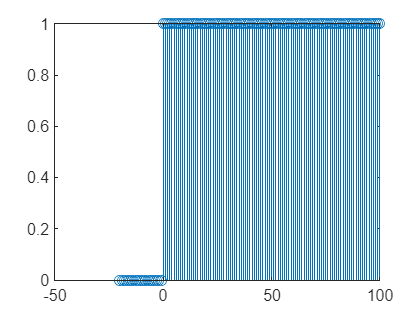

%% set unit step responce
s = 1.*(t>=0)+0.*(t<0);
stem(t,s);

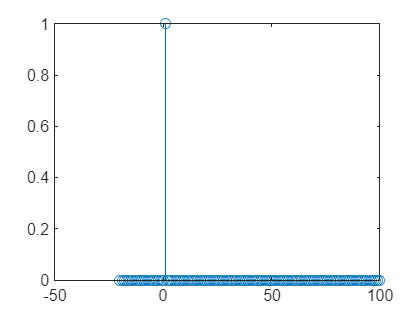

%% set inpulse responce
s_ip_r = 1.*(t==1)+0.*(t~=1);
stem(t,s_ip_r);

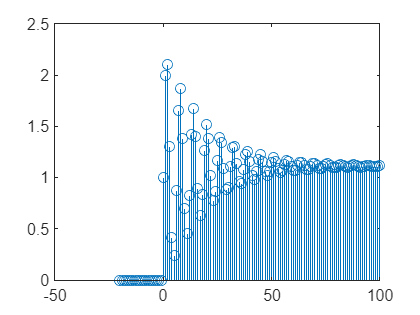


y_u = zeros(1,120);
for n = 3:121
    y_u(1,n) = y_u(1,n-1)-0.9*y_u(1,n-2)+s(1,n);
end

y_i = zeros(1,120);
for n = 3:121
    y_i(1,n) = y_i(1,n-1)-0.9*y_i(1,n-2)+s_ip_r(1,n);
end
stem(t,y_u);

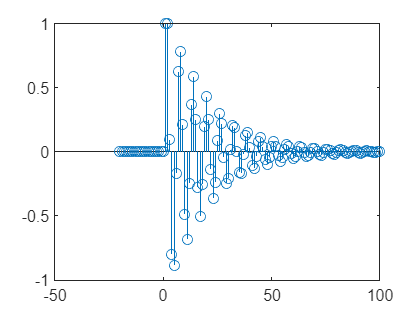

stem(t,y_i);